# DC-8 AIRCRAFT

Xdelta_e = 0;
g0 = 32.086614;
Zdelta_e = -34.6;
M = 0.84;
Iy = 3560000;
S = 2600;
c= 23;
rho = 0.000795;
a = 982;
u0 = M*a;
Xu = -0.014;
Zu = -0.0735;
Mq = -0.924;
Mdelta_e=-4.59;

Zalfa = 0;
s = tf('s');
A = 1;
q = 270;
ZdeltaT = 0;
cmalfa = -2.017;
cmalfadot = -6.62;
A_alfa = Zdelta_e/u0

A_alfa = -0.0419

Malfa = cmalfa*q*S*c/(Iy)

Malfa = -9.1479

Malfadot = cmalfadot*q*S*c/(2*Iy*u0)

Malfadot = -0.0182

A_q = Mdelta_e+Malfadot*Zdelta_e/u0

A_q = -4.5892

B = -(Mq+Malfadot+Zalfa/u0)

B = 0.9422

B_alfa = Mdelta_e-Mq*Zdelta_e/u0

B_alfa = -4.6288

B_q = Malfa*Zdelta_e/u0-Mdelta_e*Zalfa/u0

B_q = 0.3837

C = Zalfa*Mq/u0-Malfa

C = 9.1479

du_ddeltae = (Xdelta_e*s+g0*Zdelta_e/u0)/(s^2+Xu*s-Zu*g0/u0)

du_ddeltae =
 
           -1.346
  ------------------------
  s^2 - 0.014 s + 0.002859
 
Continuous-time transfer function.



dtheta_ddeltae = (-Zdelta_e*s/u0+(Xu*Zdelta_e/u0-Zu*Xdelta_e/u0))/(s^2-Xu*s-Zu*g0/u0)

dtheta_ddeltae =
 
        34.6 s + 0.4844
  ---------------------------
  824.9 s^2 + 11.55 s + 2.358
 
Continuous-time transfer function.



delalfa_dele =(A_alfa*s+B_alfa)/(A*s^2+B*s+C)

delalfa_dele =
 
    -0.04195 s - 4.629
  ----------------------
  s^2 + 0.9422 s + 9.148
 
Continuous-time transfer function.



 delh_dele = (u0/s)*(dtheta_ddeltae-delalfa_dele)

delh_dele =
 
   5.708e04 s^3 + 3.177e06 s^2 + 3.056e05 s + 1.266e04
  ------------------------------------------------------
  824.9 s^5 + 788.7 s^4 + 7559 s^3 + 107.9 s^2 + 21.57 s
 
Continuous-time transfer function.



delq_dele = (A_q*s+B_q)/(A*s^2+B*s+C)

delq_dele =
 
    -4.589 s + 0.3837
  ----------------------
  s^2 + 0.9422 s + 9.148
 
Continuous-time transfer function.



Ldelta_a = -2.11;
Lp = -1.181;
delbank_dela = Ldelta_a/(s*(s-Lp))

delbank_dela =
 
      -2.11
  -------------
  s^2 + 1.181 s
 
Continuous-time transfer function.



% delu_delT = (X_deltaT*s+(g*ZdeltaT)/u0)/(s^2+Xu*s-Zu*g/u0)

A = ss(dtheta_ddeltae)

A =
 
  A = 
             x1        x2
   x1    -0.014  -0.04574
   x2    0.0625         0
 
  B = 
         u1
   x1  0.25
   x2     0
 
  C = 
            x1       x2
   y1   0.1678  0.03758
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



A_theta = A.A;
B_theta = A.B;
if rank(ctrb(A_theta,B_theta)) == 2
    fprintf("A matrix is controllable")
end

A matrix is controllable

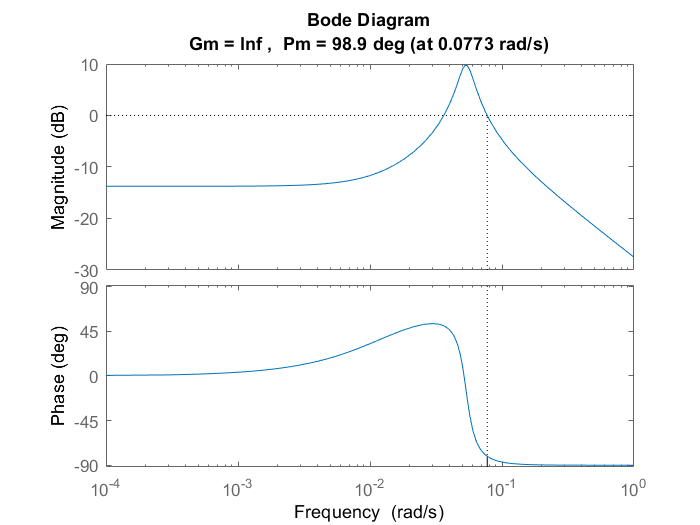

margin(dtheta_ddeltae);

A_h = ss(delh_dele);
A_he = A_h.A;
B_he = A_h.B;
 if rank(ctrb(A_he,B_he)) == 5
     fprintf("A matrix is controllable")
 end

A matrix is controllable

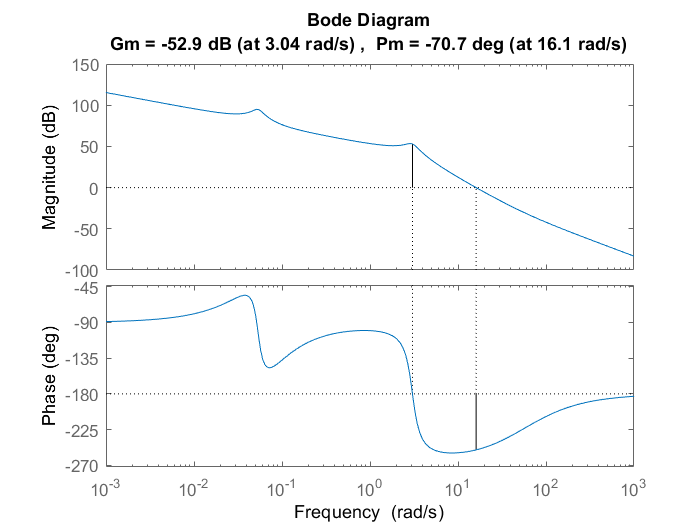

 margin(delh_dele)

 A_vel = ss(du_ddeltae);
 A1 = A_vel.A;
 B1 = A_vel.A;
 if rank(ctrb(A1,B1)) == 2
     fprintf("A matrix is controllable")
 end

A matrix is controllable

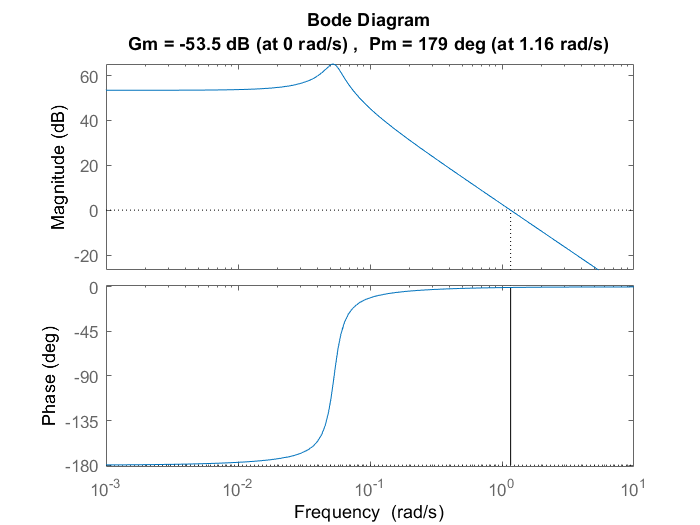

 margin(du_ddeltae)

 A_bank = ss(delbank_dela);
 A_b = A_bank.A;
B_b = A_bank.B;
if rank(ctrb(A_b,B_b)) == 2
    fprintf("A matrix is controllable")
end

A matrix is controllable

margin(delbank_dela)
